[y,yrgb]=imread("sample image.png");
ygray=rgb2gray(y);
level = graythresh(ygray);
BW=imbinarize(ygray,'global');
name=["A.png" "B.png" "C.png" "D.png" "E.png" "F.png" "G.png" "H.png" "I.png" "J.png" "K.png" "L.png" "M.png" "N.png" "Nye.png" "Ng.png" "O.png" "P.png" "Q.png" "R.png" "S.png" "T.png" "U.png" "V.png" "W.png" "X.png" "Y.png" "Z.png"];
name=name';
sizen=size(BW);
BW=gpuArray(BW);
ressim=zeros([1 size(name)]);
resnr=zeros([1 size(name)]);
resimm=zeros([1 size(name)]);
for a=1:size(name)
file='Letter reference images\'+name(a);
imref=imread(file);
imref=rgb2gray(imref);
imref=imbinarize(imref,'global');
imref=imresize(imref,sizen);
imref=gpuArray(imref);
sim1=ssim(double(BW),double(imref));
sim1=gather(sim1);
sim2=psnr(double(BW),double(imref));
sim2=gather(sim2);
sim3=immse(double(BW),double(imref));
sim3=gather(sim3);
ressim(a)=sim1;
resnr(a)=sim2;
resimm(a)=sim3;
% figure()
% imshowpair(imref,BW);title(a)
end

[Mag1,Pos1]=max(ressim);Mag1

Mag1 = 0.5567

name(Pos1)

ans = "Nye.png"

[Mag2,Pos2]=max(resnr);Mag2

Mag2 = 7.1785

name(Pos2)

ans = "Nye.png"

[Mag3,Pos3]=min(resimm);Mag3

Mag3 = 0.1915

name(Pos3)

ans = "Nye.png"

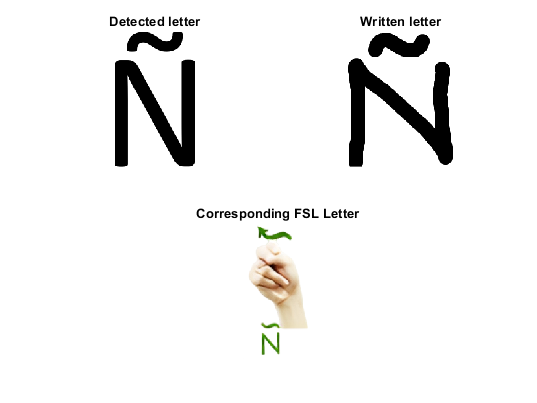


fsrname=["Ah.png" "Bh.png" "Ch.png" "Dh.png" "Eh.png" "Fh.png" "Gh.png" "Hh.png" "Ih.png" "Jh.png" "Kh.png" "Lh.png" "Mh.png" "Nh.png" "Nyeh.png" "Ngh.png" "Oh.png" "Ph.png" "Qh.png" "Rh.png" "Sh.png" "Th.png" "Uh.png" "Vh.png" "Wh.png" "Xh.png" "Yh.png" "Zh.png"];
% Poss=round(mean([Pos1 Pos2 Pos3]),0)
if (Pos1==Pos2)&&(Pos2==Pos3)&&(Pos1==Pos3)
    Poss=Pos1;
elseif (Pos1~=Pos2)&&(Pos2==Pos3)&&(Pos1~=Pos3)
    Poss=Pos2;
elseif (Pos1==Pos2)&&(Pos2~=Pos3)&&(Pos1~=Pos3)
    Poss=Pos1
end
file2='FSL reference images\'+fsrname(Poss);
file3='Letter reference images\'+name(Poss);
figout=tiledlayout(2,2);
nexttile
imshow(file3);title('Detected letter')
nexttile
imshow(y);title('Written letter')
nexttile([1 2])
imshow(file2);title('Corresponding FSL Letter')


% fileout='Letter to FSL Output\Output' + name(Poss);
% exportgraphics(figout,fileout);

% High similarity letters
% O,G,C,Q|I,J|R,P|S,P|C,S|
% Output is highly dependent on Reference letters.
% If not written almost exaclty like reference letters output is wrong.